clc
clear all

PowerIndices = [1,2,3,4]

PowerIndices =      1     2     3     4


TX_Categories = categorical({'Triangulation','WKNN-3','WKNN-4','WKNN-5'});



Noiseless = readtable("Noiseless.xlsx")

Noiseless = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       0.5089        0.0943     0.118    0.0894
    {'TX_-30'}       1.1071        0.1368     0.121    0.1386
    {'TX_-35'}       1.3364        1.2088    1.2308    1.2083
    {'TX_-40'}       0.4696        2.1024    2.1053    2.1024


NoiselessPCTError = Noiseless

NoiselessPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       0.5089        0.0943     0.118    0.0894
    {'TX_-30'}       1.1071        0.1368     0.121    0.1386
    {'TX_-35'}       1.3364        1.2088    1.2308    1.2083
    {'TX_-40'}       0.4696        2.1024    2.1053    2.1024


NoiselessPCTError{:,2:5} = (Noiseless{:,2:5}/5)*100

NoiselessPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       10.178         1.886      2.36     1.788
    {'TX_-30'}       22.142         2.736      2.42     2.772
    {'TX_-35'}       26.728        24.176    24.616    24.166
    {'TX_-40'}        9.392        42.048    42.106    42.048


NoiselessPCTError_Arr = NoiselessPCTError{:,2:5}

NoiselessPCTError_Arr =    10.1780    1.8860    2.3600    1.7880
   22.1420    2.7360    2.4200    2.7720
   26.7276   24.1760   24.6160   24.1660
    9.3920   42.0480   42.1060   42.0480


plot(PowerIndices, NoiselessPCTError_Arr, 'LineStyle',"-", 'LineWidth',1, 'Marker',"*")



Noisy = readtable("Noisy.xlsx")

Noisy = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       0.5089        0.1528    0.1319    0.1406
    {'TX_-30'}       1.1071        0.5711    0.5754    0.5682
    {'TX_-35'}       1.3364        0.6914    0.6754    0.6393
    {'TX_-40'}       0.4696        0.7643     0.767    0.7476


NoisyPCTError = Noisy

NoisyPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       0.5089        0.1528    0.1319    0.1406
    {'TX_-30'}       1.1071        0.5711    0.5754    0.5682
    {'TX_-35'}       1.3364        0.6914    0.6754    0.6393
    {'TX_-40'}       0.4696        0.7643     0.767    0.7476


NoisyPCTError{:,2:5} = (Noisy{:,2:5}/5)*100

NoisyPCTError = 4×5 table
       Var1       Triangulation     K_3       K_4       K_5  
    __________    _____________    ______    ______    ______

    {'TX_-20'}       10.178         3.056     2.638     2.812
    {'TX_-30'}       22.142        11.422    11.508    11.364
    {'TX_-35'}       26.728        13.828    13.508    12.786
    {'TX_-40'}        9.392        15.286     15.34    14.952


NoisyPCTError_Arr = NoisyPCTError{:,2:5}

NoisyPCTError_Arr =    10.1780    3.0560    2.6380    2.8120
   22.1420   11.4220   11.5080   11.3640
   26.7276   13.8280   13.5080   12.7860
    9.3920   15.2860   15.3400   14.9520


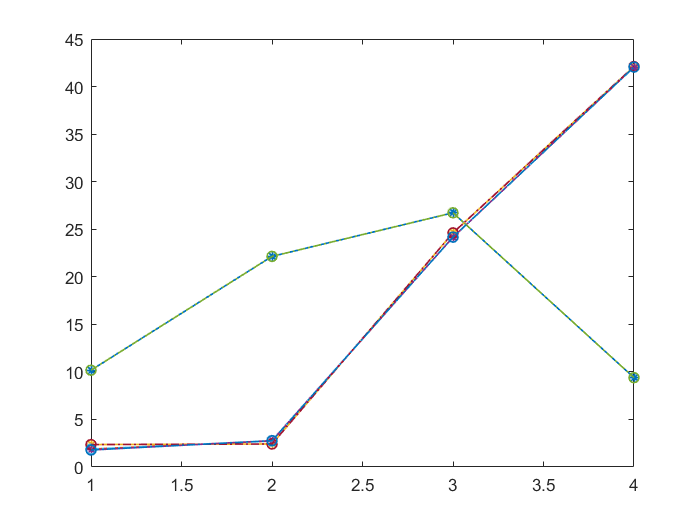

hold on
plot(PowerIndices, NoiselessPCTError_Arr, 'LineStyle',"-.", 'LineWidth',1, 'Marker',"o")

hold off

BARData1 = [NoiselessPCTError_Arr(1,1),NoisyPCTError_Arr(1,1);
                NoiselessPCTError_Arr(1,2),NoisyPCTError_Arr(1,2);
                    NoiselessPCTError_Arr(1,3),NoisyPCTError_Arr(1,3);
                      NoiselessPCTError_Arr(1,4),NoisyPCTError_Arr(1,4)]

BARData1 =    10.1780   10.1780
    1.8860    3.0560
    2.3600    2.6380
    1.7880    2.8120


b1 = bar(TX_Categories,BARData1)

b1 =   1×2 Bar array:

    Bar    Bar


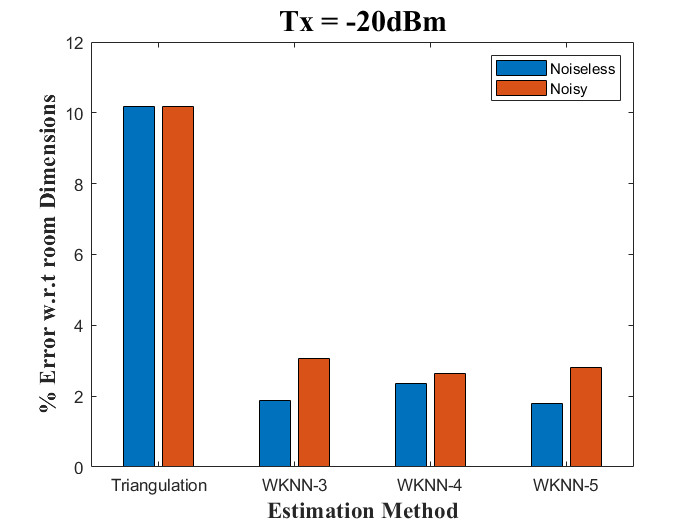

title('Tx = -20dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})


BARData2 = [NoiselessPCTError_Arr(2,1),NoisyPCTError_Arr(2,1);
                NoiselessPCTError_Arr(2,2),NoisyPCTError_Arr(2,2);
                    NoiselessPCTError_Arr(2,3),NoisyPCTError_Arr(2,3);
                      NoiselessPCTError_Arr(2,4),NoisyPCTError_Arr(2,4)]

BARData2 =    22.1420   22.1420
    2.7360   11.4220
    2.4200   11.5080
    2.7720   11.3640


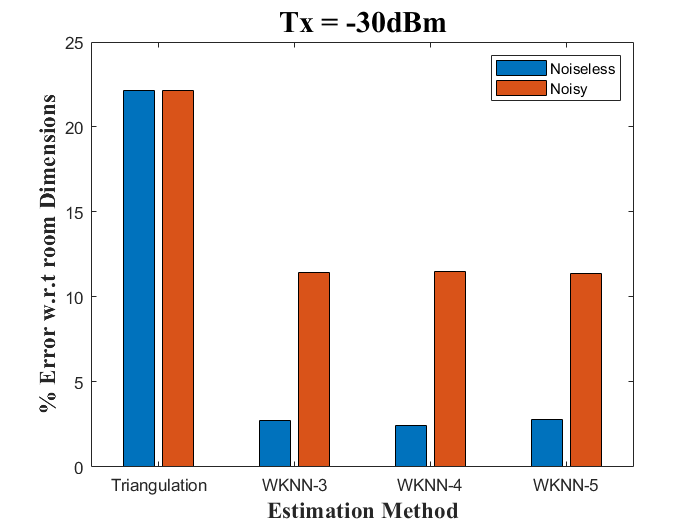


bar(TX_Categories,BARData2)
title('Tx = -30dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})


BARData3 = [NoiselessPCTError_Arr(3,1),NoisyPCTError_Arr(3,1);
                NoiselessPCTError_Arr(3,2),NoisyPCTError_Arr(3,2);
                    NoiselessPCTError_Arr(3,3),NoisyPCTError_Arr(3,3);
                      NoiselessPCTError_Arr(3,4),NoisyPCTError_Arr(3,4)]    

BARData3 =    26.7276   26.7276
   24.1760   13.8280
   24.6160   13.5080
   24.1660   12.7860


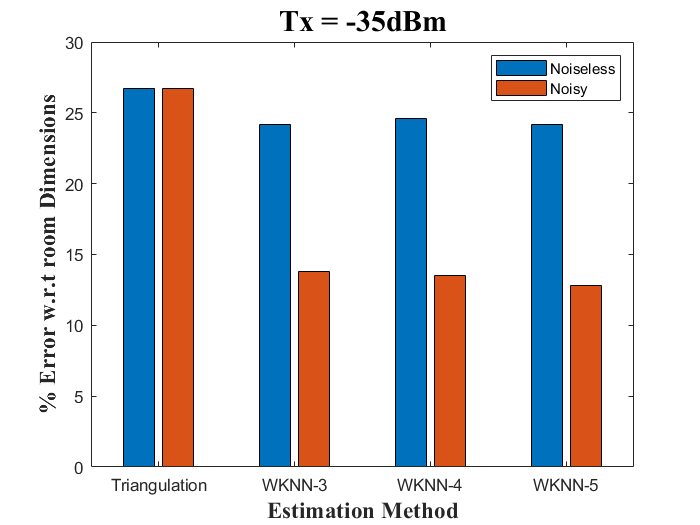

bar(TX_Categories,BARData3)
title('Tx = -35dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})


BARData4 = [NoiselessPCTError_Arr(4,1),NoisyPCTError_Arr(4,1);
                NoiselessPCTError_Arr(4,2),NoisyPCTError_Arr(4,2);
                    NoiselessPCTError_Arr(4,3),NoisyPCTError_Arr(4,3);
                      NoiselessPCTError_Arr(4,4),NoisyPCTError_Arr(4,4)]    

BARData4 =     9.3920    9.3920
   42.0480   15.2860
   42.1060   15.3400
   42.0480   14.9520


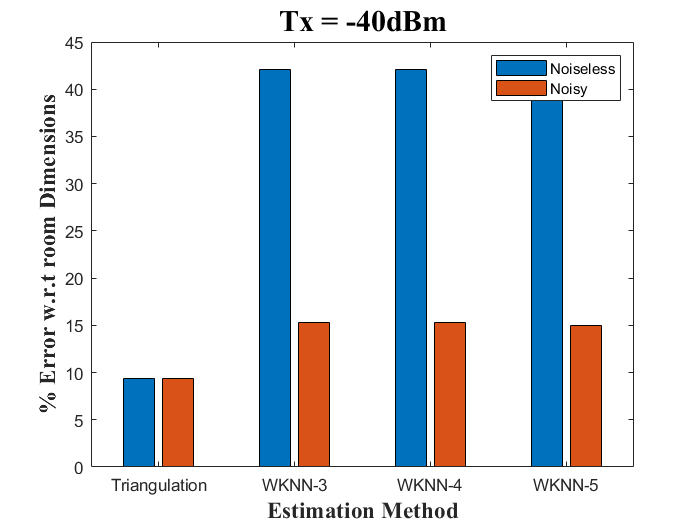

bar(TX_Categories,BARData4)
title('Tx = -40dBm',"FontSize",18,'FontWeight','bold','FontName','Times')
xlabel('Estimation Method',"FontSize",14,'FontWeight','bold','FontName','Times')
ylabel('% Error w.r.t room Dimensions',"FontSize",14,'FontWeight','bold','FontName','Times')
legend({'Noiseless', 'Noisy'})